# **Signals and Systems**

## **Experiment No. # 14**

### Objective: 

In this lab, students will learn how to create transfer functions in MATLAB and Simulink,  and to use them further to find step and impulse response of a signal.

### Theoretical Background: 

#### Transfer Functions: 

A transfer function is a mathematical function relating the output or response of a system,  such as a filter, to the input. For example:

The transfer function may be written in z-domain or in s-domain (or Laplace domain).

### Tasks: 

The following tasks are to be performed by the students: 

### Task 1: 

Using the ‘TF’ and ‘ZPK’ commands, create two transfer functions. Plot the step and impulse  response of each transfer function. The transfer functions to be generated are: 

Using ‘tf’ command: 

𝑠 + 1 / 6𝑠^5 + 5𝑠^4 + 4𝑠^3 + 3𝑠^2 + 2𝑠 + 1 

Using ‘zpk’ command: 

2(𝑠 − 1)(𝑠 − 2) / (𝑠 + 1)(𝑠 + 2)(𝑠 + 3)(𝑠 + 4)(𝑠 + 5) 

### Task 2: 

In Simulink, take three step functions. Add them and apply a transfer function to the result.  View the input and output in scope, and also export the result to workspace. Also view the  result in case of one step function only. The transfer function to be applied to the input is: 

𝑠 + 1 / 6𝑠^5 + 5𝑠^4 + 4𝑠^3 + 3𝑠^2 + 2𝑠 + 1 

#### Task 1:

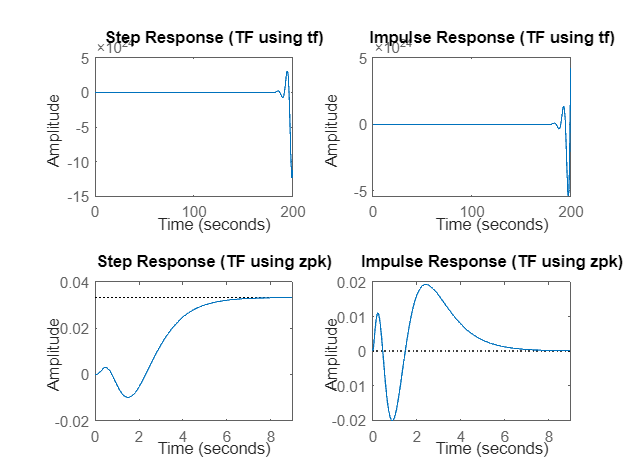

% Transfer function using 'tf' command
num_tf = [1, 1];
denum_tf = [6, 5, 4, 3, 2, 1];
TF_tf = tf(num_tf, denum_tf);

% Transfer function using 'zpk' command
zeros_zpk = [1, 2];
poles_zpk = [-1, -2, -3, -4, -5];
gain_zpk = 2;
TF_zpk = zpk(zeros_zpk, poles_zpk, gain_zpk);

% Plot step and impulse responses for the transfer function created using 'tf'
figure;
subplot(2,2,1);
step(TF_tf);
title('Step Response (TF using tf)');

subplot(2,2,2);
impulse(TF_tf);
title('Impulse Response (TF using tf)');

% Plot step and impulse responses for the transfer function created using 'zpk'
subplot(2,2,3);
step(TF_zpk);
title('Step Response (TF using zpk)');

subplot(2,2,4);
impulse(TF_zpk);
title('Impulse Response (TF using zpk)');